%%CG assignemnt testsing script

clear; clc; close all;

%Q2


tau_q2   = 20;

noise_q2 = 0.005;

tol      = 1e-8;

max_iter = 5000;

sizes = [512, 1024, 2048];   

fprintf('=== Question 2 ===\n');

=== Question 2 ===



figure('Name','Q2 – Relative Residual vs Iteration');
colors = lines(numel(sizes));


for s = 1:numel(sizes)
   
    
    N = sizes(s);
    
    [A, b] = get_covariance_matrix(N, tau_q2, noise_q2);
    
    tic;
    [x, iter, rel_res] = cg_solver(A, b, tol, max_iter);
    t = toc;
    
    
    fprintf('N = %4d | iterations = %4d | final rel. res = %.3e | time = %.2fs\n', ...
        N, iter, rel_res(end), t);
    
    
    
    semilogy(1:iter, rel_res, 'Color', colors(s,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('N = %d', N));
    
    
    hold on;


end

N =  512 | iterations =  352 | final rel. res = 9.706e-09 | time = 0.01s
N = 1024 | iterations =  548 | final rel. res = 5.612e-09 | time = 0.03s
N = 2048 | iterations =  720 | final rel. res = 8.784e-09 | time = 0.23s


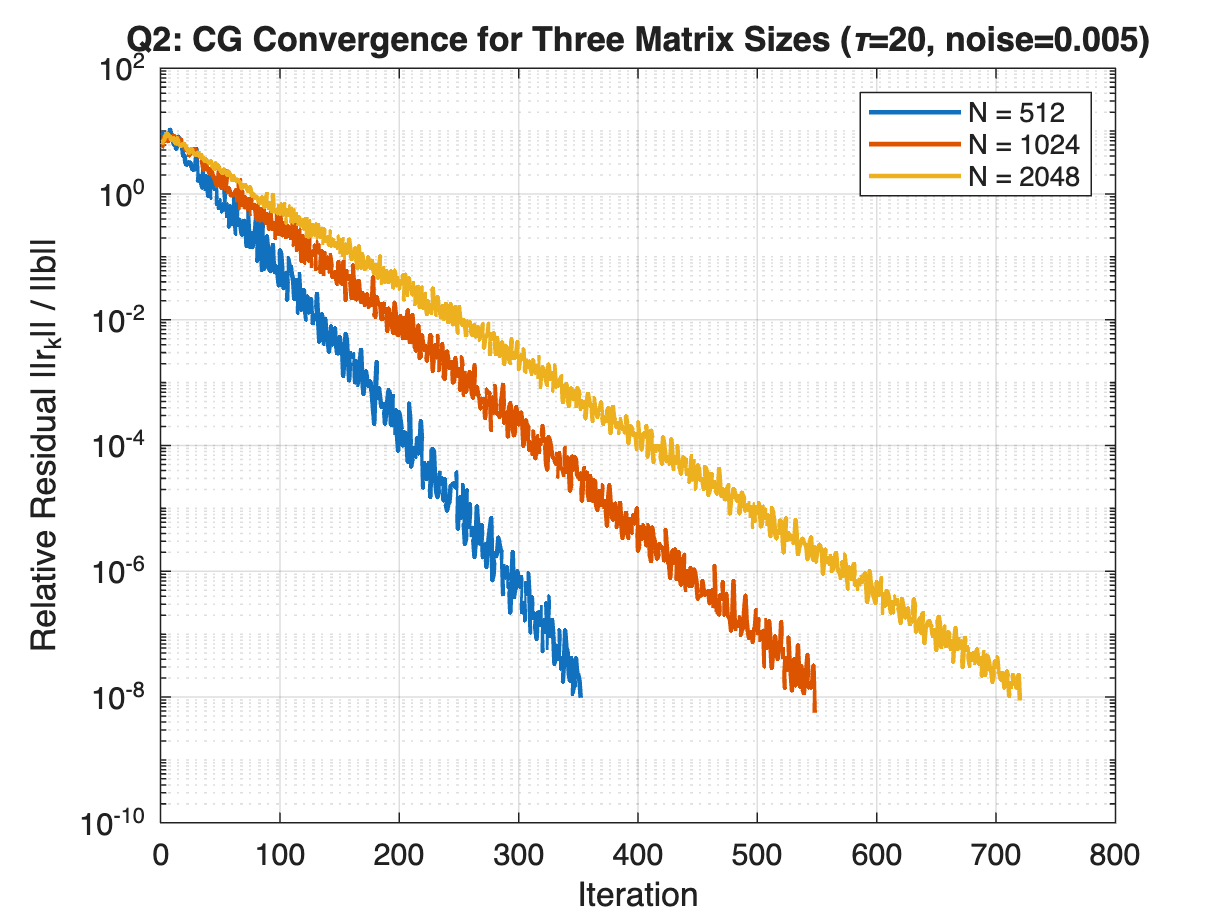


xlabel('Iteration'); ylabel('Relative Residual ||r_k|| / ||b||');
title('Q2: CG Convergence for Three Matrix Sizes (\tau=20, noise=0.005)');
legend show; grid on;


%Q3
tau_q3 = 898;   %student no. 


noise_levels = [0.5, 0.1, 0.05, 0.01, 0.005, 0.001, 1e-4, 1e-5, 5e-8];


N_q3 = 512;     

fprintf('\n=== Question 3  (tau = %d) ===\n', tau_q3);


=== Question 3  (tau = 898) ===



fprintf('%-12s  %-12s  %-18s  %-18s\n', ...
    'noise', 'iter', 'final rel.res', 'cond(A)');

noise         iter          final rel.res       cond(A)           



iter_q3   = zeros(size(noise_levels));
cond_q3   = zeros(size(noise_levels));

for i = 1:numel(noise_levels)
    [A, b] = get_covariance_matrix(N_q3, tau_q3, noise_levels(i));
    [~, it, rel_res] = cg_solver(A, b, tol, max_iter);
    
    
    kappa = cond(A);  
    
    iter_q3(i) = it;
    
    cond_q3(i) = kappa;
    
    fprintf('%-12.2e  %-12d  %-18.3e  %-18.3e\n', ...
        noise_levels(i), it, rel_res(end), kappa);
end

5.00e-01      11            7.490e-10           9.682e+02         
1.00e-01      14            5.647e-09           4.837e+03         
5.00e-02      18            6.596e-10           9.673e+03         
1.00e-02      27            5.259e-10           4.836e+04         
5.00e-03      28            4.891e-09           9.672e+04         
1.00e-03      48            6.569e-09           4.836e+05         
1.00e-04      101           7.895e-09           4.836e+06         
1.00e-05      251           9.394e-09           4.835e+07         
5.00e-08      3025          9.878e-09           9.557e+09         


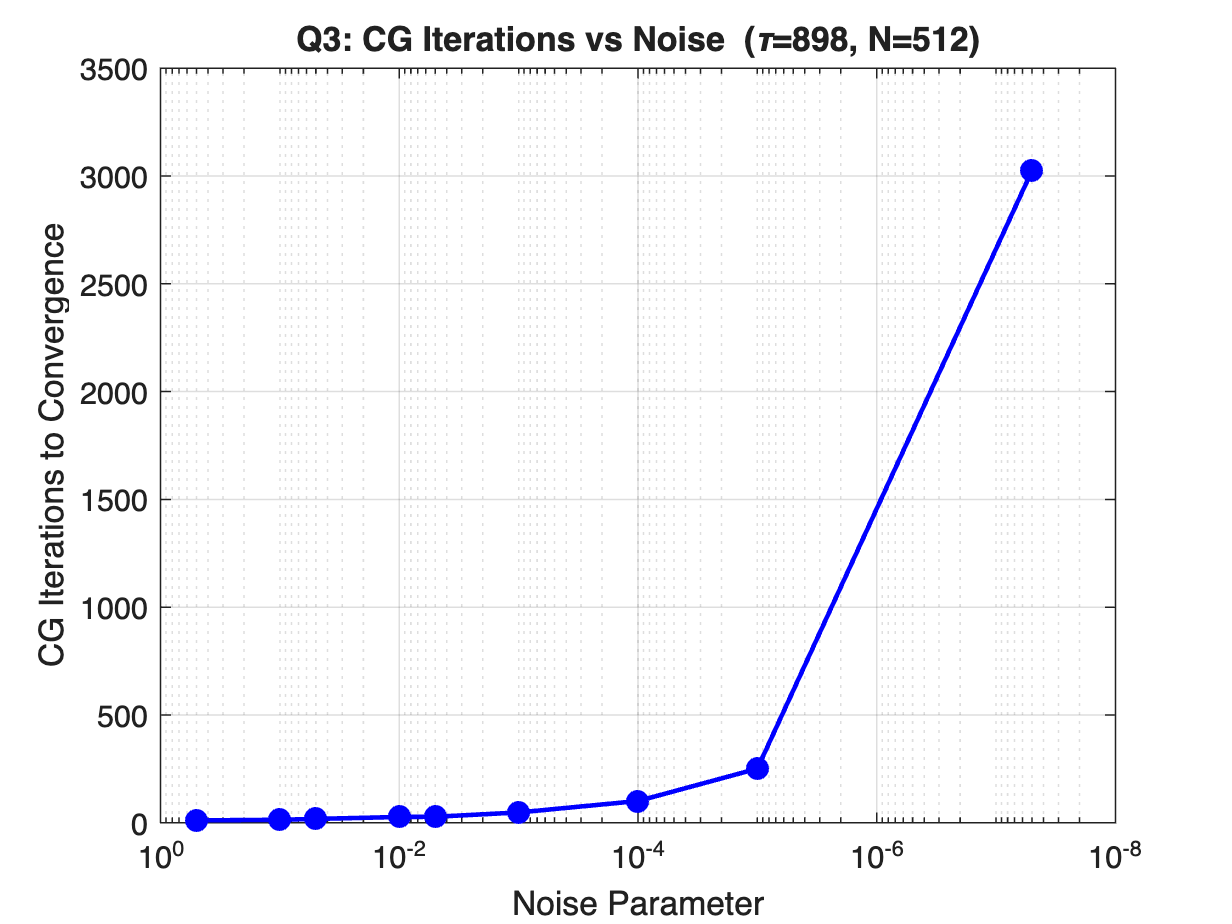


figure('Name','Q3 – Iterations vs Noise');
semilogx(noise_levels, iter_q3, 'b-o', 'LineWidth', 1.5, 'MarkerFaceColor','b');
set(gca,'XDir','reverse');
xlabel('Noise Parameter'); ylabel('CG Iterations to Convergence');


title(sprintf('Q3: CG Iterations vs Noise  (\\tau=%d, N=%d)', tau_q3, N_q3));
grid on;

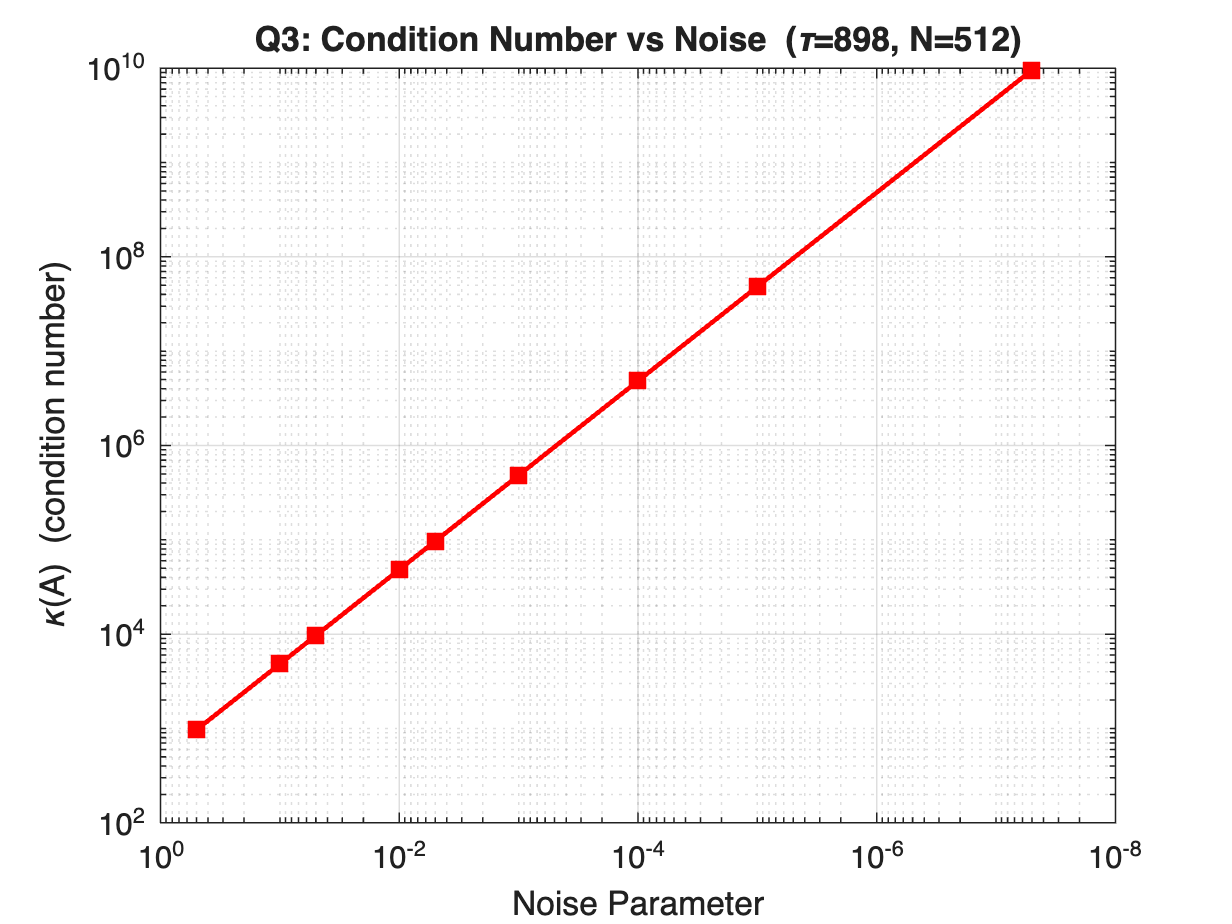


figure('Name','Q3 – Condition Number vs Noise');
loglog(noise_levels, cond_q3, 'r-s', 'LineWidth', 1.5, 'MarkerFaceColor','r');
set(gca,'XDir','reverse');
xlabel('Noise Parameter'); ylabel('\kappa(A)  (condition number)');
title(sprintf('Q3: Condition Number vs Noise  (\\tau=%d, N=%d)', tau_q3, N_q3));
grid on;


%Q4

fprintf('\n=== Question 4 ===\n');


=== Question 4 ===


N_q4    = 1024;
tau_q4  = 100;
noise_q4 = 0.05;

[A, b] = get_covariance_matrix(N_q4, tau_q4, noise_q4);


[x_A, iter_A, res_A] = cg_solver(A, b, tol, max_iter);
fprintf('Original A    | iterations = %d | final rel.res = %.3e\n', iter_A, res_A(end));

Original A    | iterations = 112 | final rel.res = 7.446e-09



%preconditioned system

M      = chol(A);              
A_new  = M \ (A / M');         
b_new  = M \ b;                


[x_new, iter_new, res_new] = cg_solver(A_new, b_new, tol, max_iter);
fprintf('Precond A_new | iterations = %d | final rel.res = %.3e\n', iter_new, res_new(end));

Precond A_new | iterations = 12 | final rel.res = 3.386e-10




x_recovered = M' \ x_new;
fprintf('Solution consistency: ||x_A - x_recovered|| / ||x_A|| = %.3e\n', ...
    norm(x_A - x_recovered) / norm(x_A));

Solution consistency: ||x_A - x_recovered|| / ||x_A|| = 3.942e-09





fprintf('Computing eigenvalues (may take a moment)...\n');

Computing eigenvalues (may take a moment)...


eigs_A     = eig(A);
eigs_Anew  = eig(A_new);

fprintf('cond(A)     = %.4e\n', max(eigs_A)   / min(eigs_A));

cond(A)     = 4.4024e+03


fprintf('cond(A_new) = %.4e\n', max(eigs_Anew)/ min(eigs_Anew));

cond(A_new) = 4.5838e+04


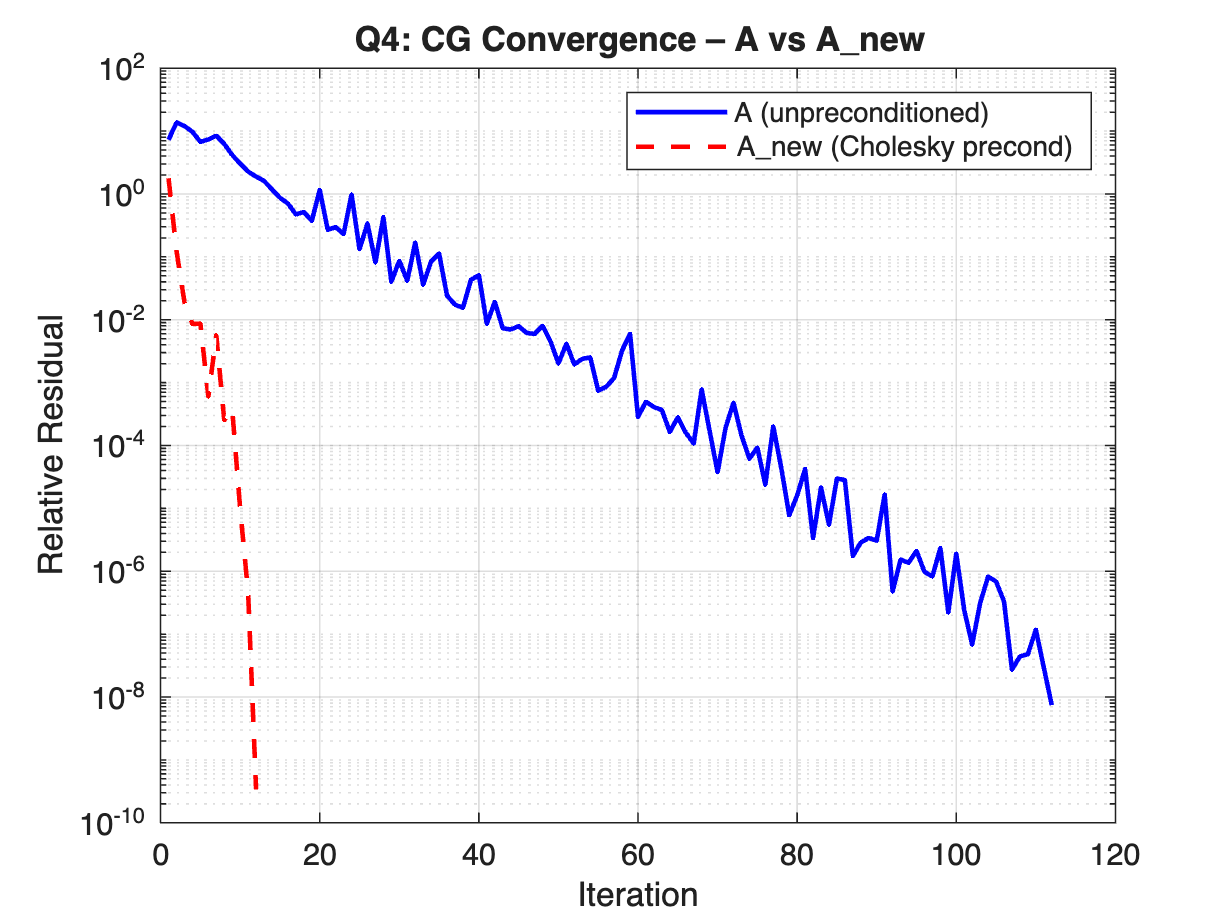



figure('Name','Q4 – Convergence Comparison');
semilogy(1:iter_A,   res_A,   'b-',  'LineWidth', 1.5, 'DisplayName', 'A (unpreconditioned)');
hold on;
semilogy(1:iter_new, res_new, 'r--', 'LineWidth', 1.5, 'DisplayName', 'A\_new (Cholesky precond)');
xlabel('Iteration'); ylabel('Relative Residual');
title('Q4: CG Convergence – A vs A\_new');
legend show; grid on;

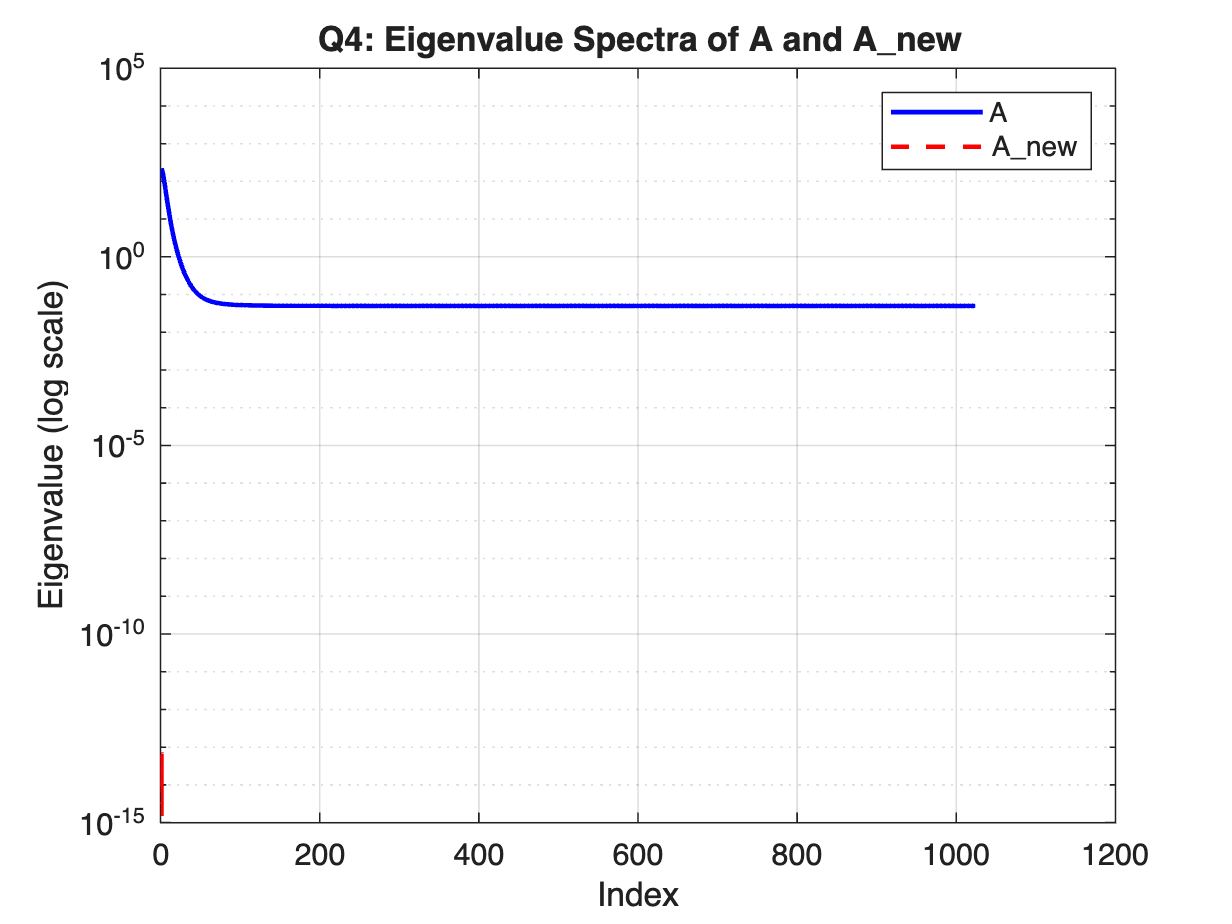



figure('Name','Q4 – Eigenvalue Spectra');
semilogy(sort(eigs_A,    'descend'), 'b-',  'LineWidth', 1.5, 'DisplayName', 'A');
hold on;
semilogy(sort(eigs_Anew, 'descend'), 'r--', 'LineWidth', 1.5, 'DisplayName', 'A\_new');
xlabel('Index'); ylabel('Eigenvalue (log scale)');
title('Q4: Eigenvalue Spectra of A and A\_new');
legend show; grid on;